rng(1);
dcl_init;
smpl_per_symbl = 64;
pkt_size = 10^5;
k = 2;
M = 4;
modulation = 'fsk';
fs = 10^7;
flag_gray_encode = 0;

## Part 1:

### 1.

b_tx = bit_gen(pkt_size, k);

### 2. 

b_tx_dec = bi2de(b_tx, 'left-msb');
sym_idx = b_tx_dec + 1;

### 3.

cons = constellation(M, smpl_per_symbl, fs);
[tx_smpl] = pulse_modulation(fs, smpl_per_symbl, b_tx_dec, pkt_size, M);

% figure
% plot((1:pkt_size*smpl_per_symbl), real(tx_smpl))
% hold on
% plot((1:pkt_size*smpl_per_symbl), imag(tx_smpl))
% hold off
% axis tight
% legend({'real part', 'imaginary part'})

## Part 2:

### 1.

tx_sampl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl];

### 2.

rx_smpl = tx_sampl_delayed * exp(1j * chnl_phase_offset);

### 3.

Es_avg = sum(abs(cons).^2) / M

Es_avg = 1

Eb = Es_avg / k

Eb = 0.5000


snr_db = 10;
var_noise = Eb / power(10, (snr_db / 10))

var_noise = 0.0500


l = length(tx_smpl);
noise_smpl = (sqrt(var_noise/2) * randn(l, 1) + 1j * sqrt(var_noise/2) * randn(l, 1));
rx_smpl_noise = noise_smpl + rx_smpl;

## Part 3:

### 1.

%rx_smpl = rx_smpl_noise;
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise, modulation, M, fs, smpl_per_symbl);

### 2.

if flag_gray_encode == 1
    det_bit = b_gray(det_sym_idx, :);
else
    det_bit = de2bi(det_sym_idx-1, 'left-msb');
end

### 3.

ser = sum(det_sym_idx ~= sym_idx) / pkt_size

ser = 1.0000e-05

### 4.

ber = sum((det_bit ~= b_tx), 'all') / (pkt_size * k)

ber = 5.0000e-06

## Part 4:

### 1.

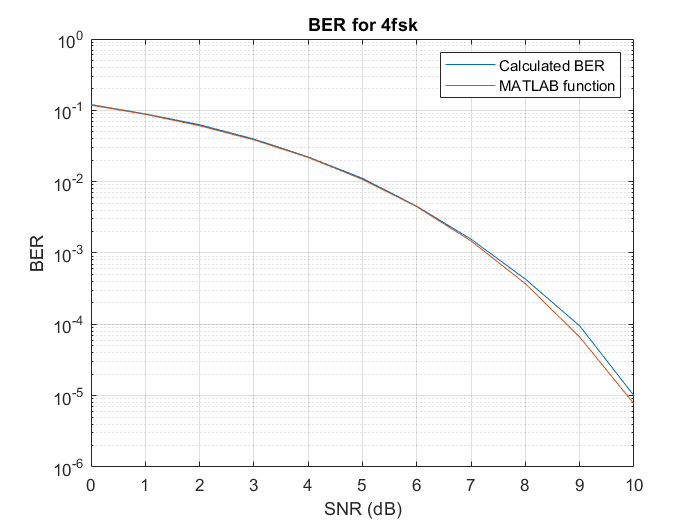

Es_avg = sum(abs(cons).^2) / M;
Eb = Es_avg / k;
EbN0 = 0:10;
varnoise = Eb ./ power(10, (EbN0 / 10));
ber = zeros(1, 11);
for c = 1:11
    noise_smpl = (sqrt(varnoise(c)/2) * randn(l, 1) + 1j * sqrt(varnoise(c)/2) * randn(l, 1));
    rx_smpl_noise = noise_smpl + rx_smpl;
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise, modulation, M, fs, smpl_per_symbl);
    det_bit = de2bi(det_sym_idx-1, 'left-msb');
    ber(c) = sum((det_bit ~= b_tx), 'all') / (pkt_size * k);
end
ber_MATLAB = berawgn(EbN0_dB, modulation, M, 'coherent');

figure
semilogy(EbN0, ber)
hold on
semilogy(EbN0, ber_MATLAB)
hold off
legend({'Calculated BER', 'MATLAB function'})
xlabel('SNR (dB)')
ylabel('BER')
title(['BER for ', num2str(M), modulation])
grid

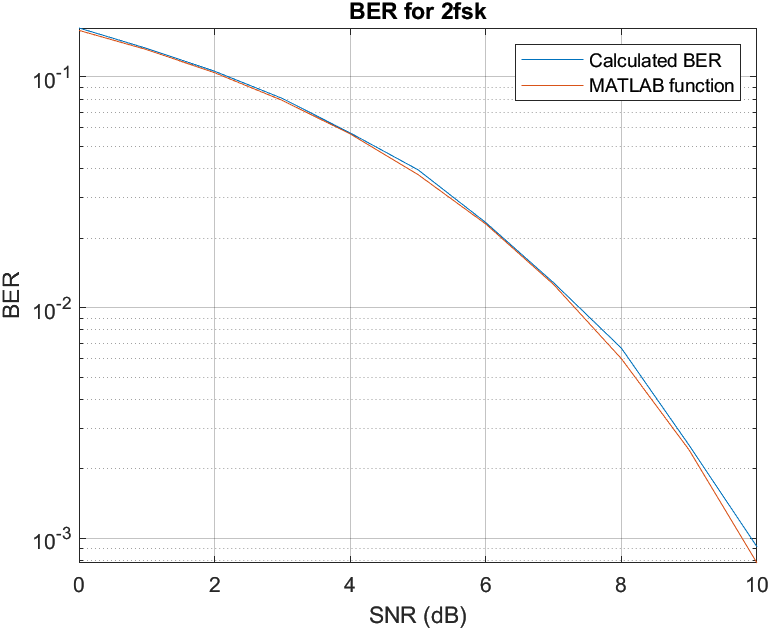 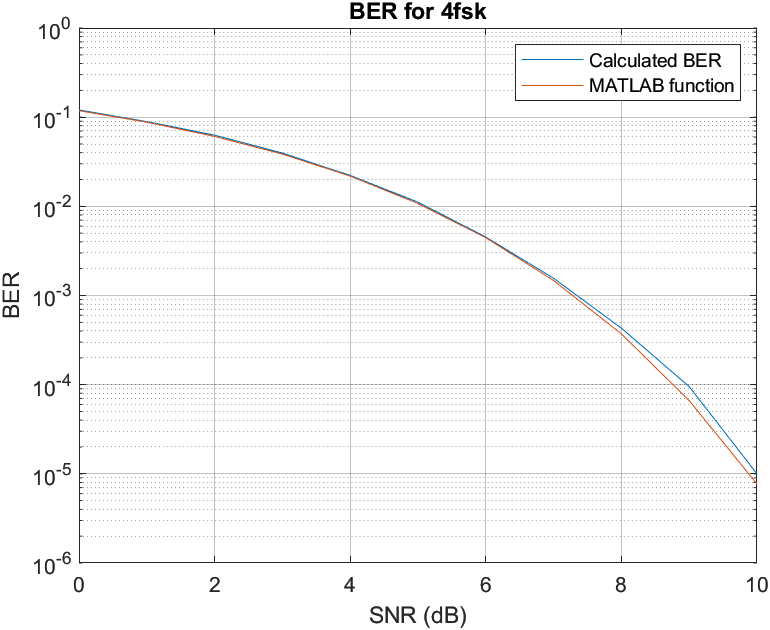 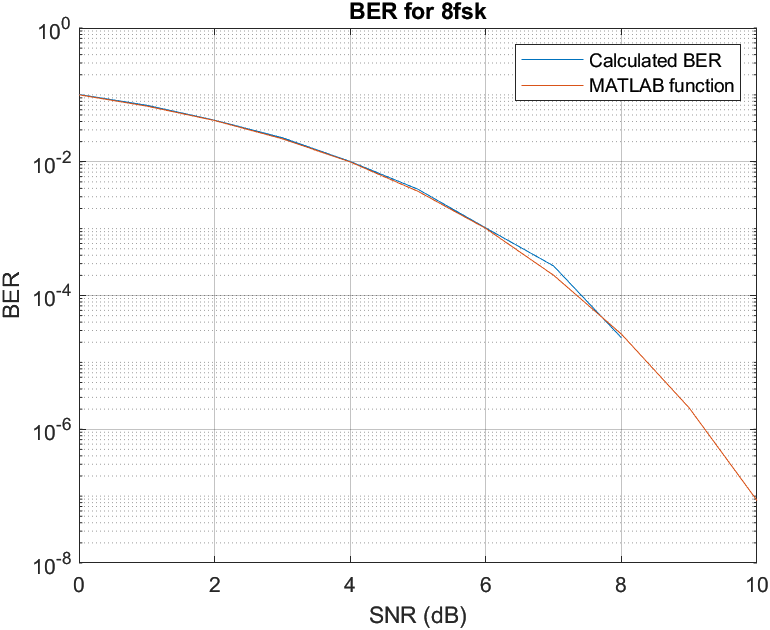

As the above plots show, since there is no channel delay or phase offset the calculated BER and berawgn function plots are compatible.

### 2.

#### step 1:

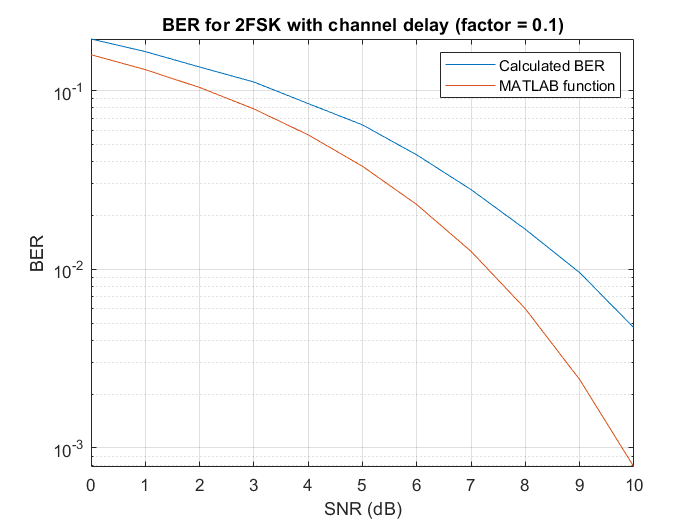

M = 2;
k = 1;
b_tx = bit_gen(pkt_size, k);
b_tx_dec = bi2de(b_tx, 'left-msb');
sym_idx = b_tx_dec + 1;
chnl_delay_in_smpl = fix(0.1 * smpl_per_symbl);
cons = constellation(M, smpl_per_symbl, fs);
[tx_smpl] = pulse_modulation(fs, smpl_per_symbl, b_tx_dec, pkt_size, M);
tx_sampl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl];
rx_smpl = tx_sampl_delayed;
l = length(rx_smpl);
Es_avg = sum(abs(cons).^2) / M;
Eb = Es_avg / k;
EbN0 = 0:10;
varnoise = Eb ./ power(10, (EbN0 / 10));
ber = zeros(1, 11);

for c = 1:11
    noise_smpl = (sqrt(varnoise(c)/2) * randn(l, 1) + 1j * sqrt(varnoise(c)/2) * randn(l, 1));
    rx_smpl_noise = noise_smpl + rx_smpl;
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise, modulation, M, fs, smpl_per_symbl);
    det_bit = de2bi(det_sym_idx-1, 'left-msb');
    ber(c) = sum((det_bit(1:length(b_tx)) ~= b_tx), 'all') / (pkt_size * k);
end
ber_MATLAB = berawgn(EbN0, modulation, M, 'coherent');

figure
semilogy(EbN0, ber)
hold on
semilogy(EbN0, ber_MATLAB)
hold off
legend({'Calculated BER', 'MATLAB function'})
xlabel('SNR (dB)')
ylabel('BER')
title('BER for 2FSK with channel delay (factor = 0.1)')
grid

  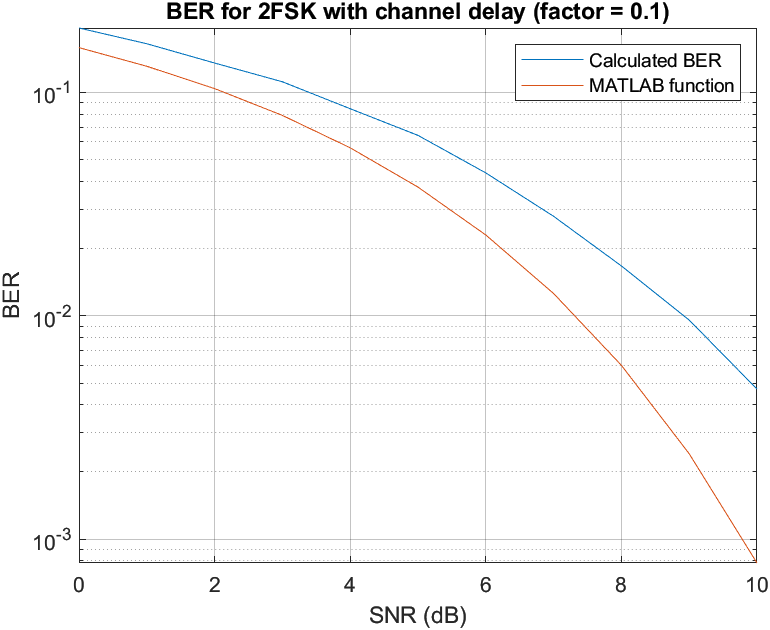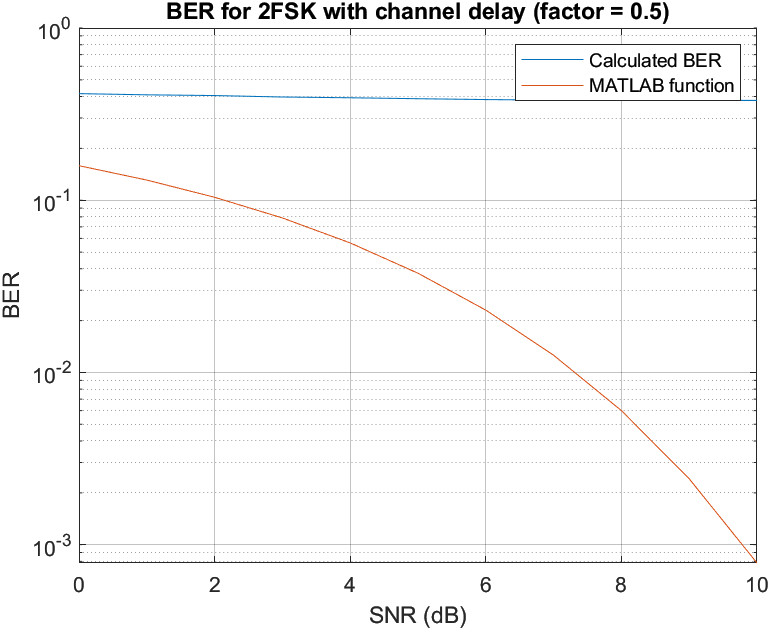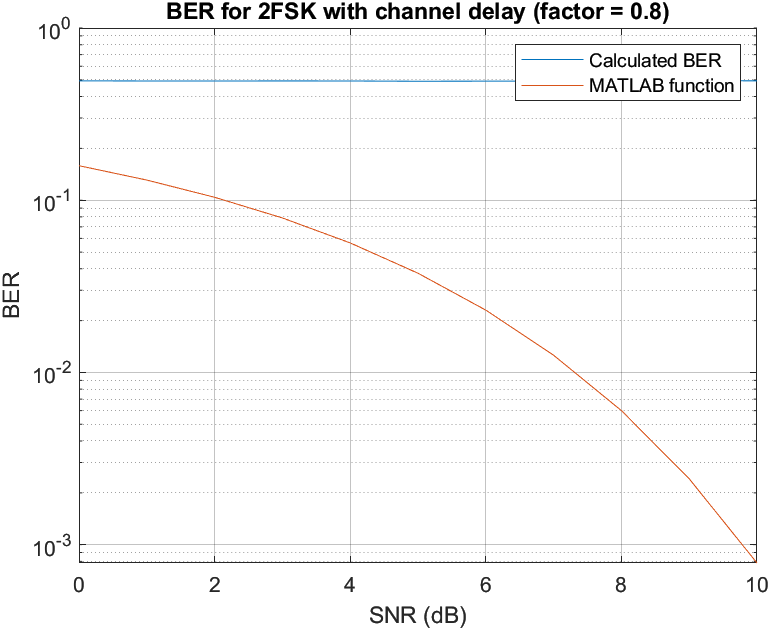

As we can see, increasing channel delay will increase BER. Because as channel delay increase, more bits of adjacent symbols will be mixed. 

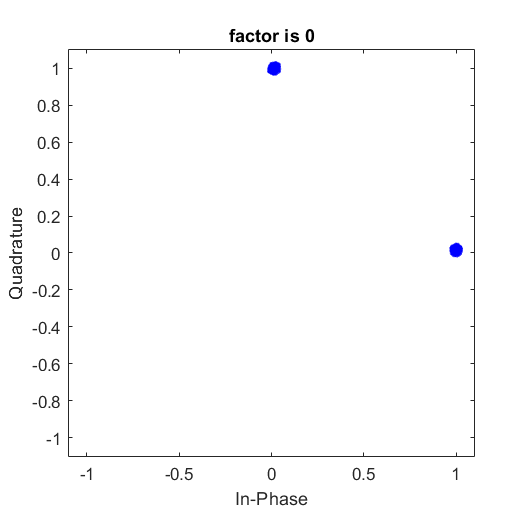

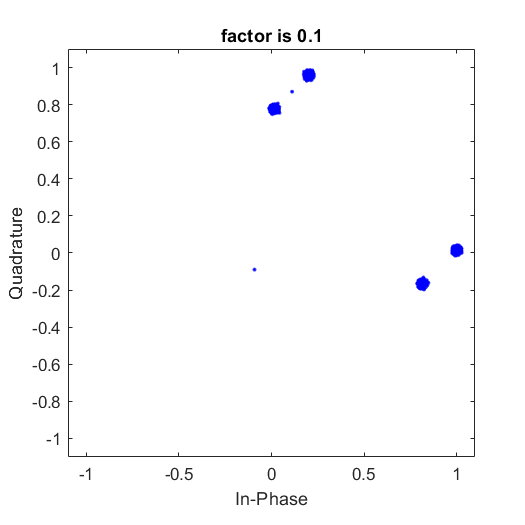

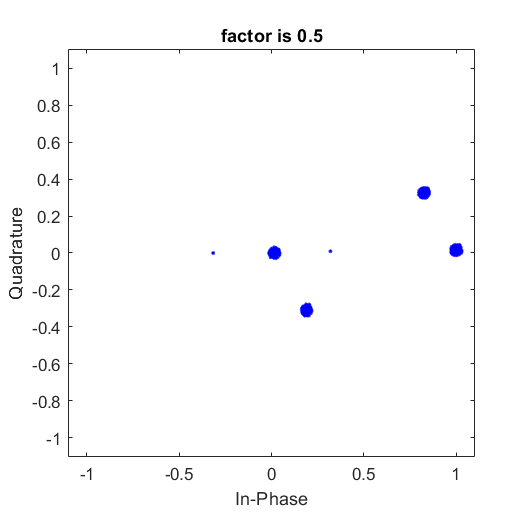

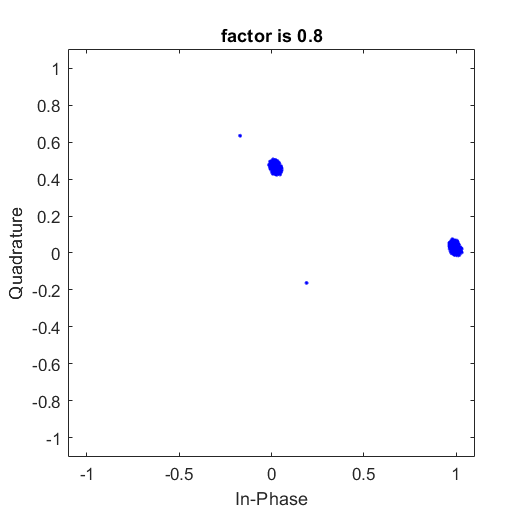

scatter_flag = 1;
M = 2;
k = 1;
b_tx = bit_gen(pkt_size, k);
b_tx_dec = bi2de(b_tx, 'left-msb');
sym_idx = b_tx_dec + 1;
factor = [0 0.1 0.5 0.8];
cons = constellation(M, smpl_per_symbl, fs);
[tx_smpl] = pulse_modulation(fs, smpl_per_symbl, b_tx_dec, pkt_size, M);
Es_avg = sum(abs(cons).^2) / M;
Eb = Es_avg / k;
varnoise = Eb / power(10, (40 / 10));

for c = 1:4
    chnl_delay_in_smpl = fix(factor(c) * smpl_per_symbl);
    tx_sampl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl];
    rx_smpl = tx_sampl_delayed;
    l = length(rx_smpl);
    noise_smpl = (sqrt(varnoise/2) * randn(l, 1) + 1j * sqrt(varnoise/2) * randn(l, 1));
    rx_smpl_noise = noise_smpl + rx_smpl;
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise, modulation, M, fs, smpl_per_symbl, scatter_flag, factor(c));
end

Because of the channel delay that cuases bits of adjacent symbols to be mixed, scattering plot will change as well.

#### step 2:

b_tx = bit_gen(pkt_size, k);
b_tx_dec = bi2de(b_tx, 'left-msb');
sym_idx = b_tx_dec + 1;
cons = constellation(M, smpl_per_symbl, fs);
[tx_smpl] = pulse_modulation(fs, smpl_per_symbl, b_tx_dec, pkt_size, M);

hder_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k);
hder_dec = bi2de(hder_bit, 'left-msb');

hder_b_tx_dec = [hder_dec; b_tx_dec];

[tx_smpl] = pulse_modulation(fs, smpl_per_symbl, hder_b_tx_dec, pkt_size, M);
hdr_smpl = tx_smpl(1:length(hder_dec)*smpl_per_symbl);

chnl_delay_in_smpl = fix(0.5 * smpl_per_symbl);
tx_sampl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl];

#### step 3:

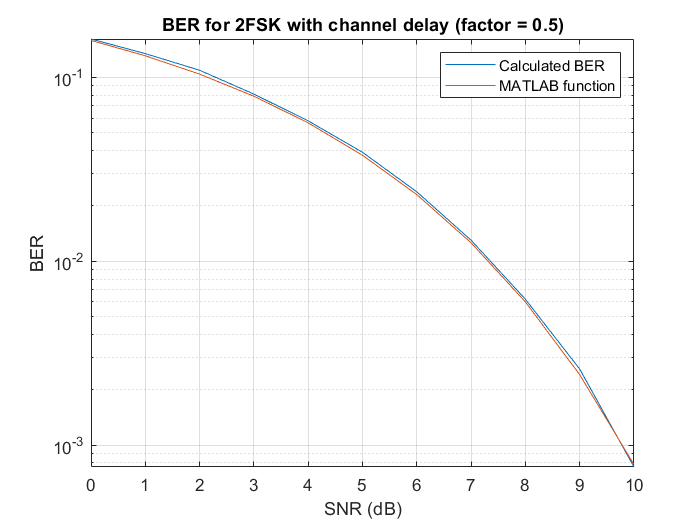

rx_smpl = tx_sampl_delayed;
l = length(rx_smpl);
EbN0 = 0:10;
Es_avg = sum(abs(cons).^2) / M;
Eb = Es_avg / k;
varnoise = Eb ./ power(10, (EbN0 / 10));
ber = zeros(1, 11);

for c = 1:11
    noise_smpl = (sqrt(varnoise(c)/2) * randn(l, 1) + 1j * sqrt(varnoise(c)/2) * randn(l, 1));
    rx_smpl_noise = noise_smpl + rx_smpl;
    [corr, lags] = xcorr(rx_smpl_noise, hdr_smpl);
    corr = corr(lags >= 0);
    [~, idx_max] = max(corr);
    rx_smpl_noise = rx_smpl_noise(idx_max + length(hdr_smpl):end, 1);
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise, modulation, M, fs, smpl_per_symbl);
    det_bit = de2bi(det_sym_idx-1, 'left-msb');
    ber(c) = sum((det_bit ~= b_tx), 'all') / (pkt_size * k);
end
ber_MATLAB = berawgn(EbN0, modulation, M, 'coherent');

figure
semilogy(EbN0, ber)
hold on
semilogy(EbN0, ber_MATLAB)
hold off
legend({'Calculated BER', 'MATLAB function'})
xlabel('SNR (dB)')
ylabel('BER')
title('BER for 2FSK with channel delay (factor = 0.5)')
grid

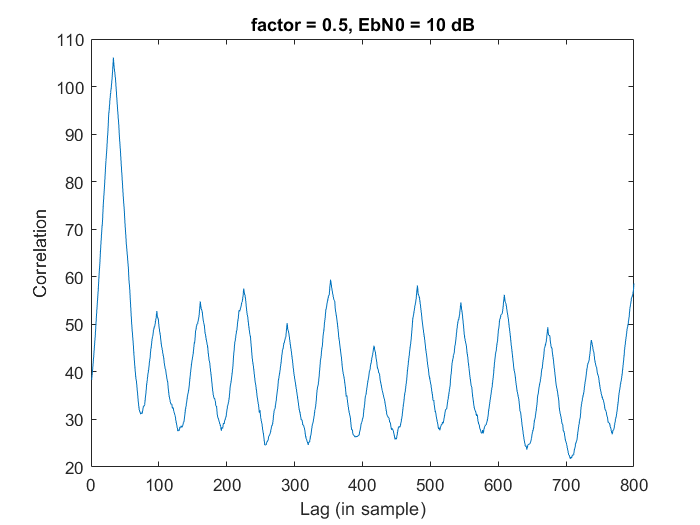

plot(1:800, abs(corr(1:800)))
xlabel('Lag (in sample)')
ylabel('Correlation')
title('factor = 0.5, EbN0 = 10 dB')

### 3. step 1:

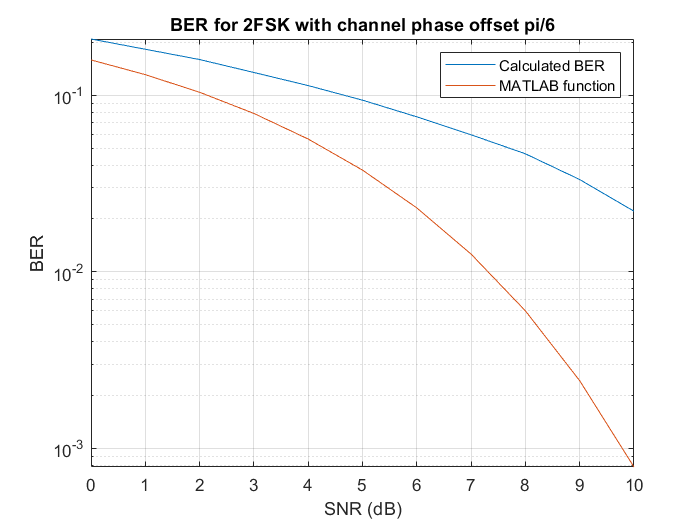

chnl_phase_offset = pi / 6;
[tx_smpl] = pulse_modulation(fs, smpl_per_symbl, b_tx_dec, pkt_size, M);
l = length(tx_smpl);
EbN0 = 0:10;
Es_avg = sum(abs(cons).^2) / M;
Eb = Es_avg / k;
varnoise = Eb ./ power(10, (EbN0 / 10));
ber = zeros(1, 11);

for c = 1:11
    noise_smpl = (sqrt(varnoise(c)/2) * randn(l, 1) + 1j * sqrt(varnoise(c)/2) * randn(l, 1));
    rx_smpl_noise = noise_smpl + tx_smpl;
    rx_smpl = rx_smpl_noise * exp(1j * chnl_phase_offset);
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl);
    det_bit = de2bi(det_sym_idx-1, 'left-msb');
    ber(c) = sum((det_bit ~= b_tx), 'all') / (pkt_size * k);
end
ber_MATLAB = berawgn(EbN0, modulation, M, 'coherent');

figure
semilogy(EbN0, ber)
hold on
semilogy(EbN0, ber_MATLAB)
hold off
legend({'Calculated BER', 'MATLAB function'})
xlabel('SNR (dB)')
ylabel('BER')
title('BER for 2FSK with channel phase offset pi/6')
grid

#### 3. step 2:

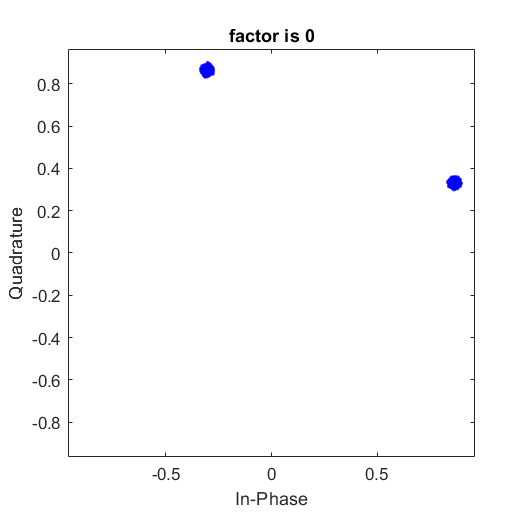

M = 2;
k = 1;
b_tx = bit_gen(pkt_size, k);
b_tx_dec = bi2de(b_tx, 'left-msb');
sym_idx = b_tx_dec + 1;
cons = constellation(M, smpl_per_symbl, fs);
[tx_smpl] = pulse_modulation(fs, smpl_per_symbl, b_tx_dec, pkt_size, M);
Es_avg = sum(abs(cons).^2) / M;
Eb = Es_avg / k;
varnoise = Eb / power(10, (40 / 10));
chnl_phase_offset = pi / 6;
l = length(tx_smpl);

noise_smpl = (sqrt(varnoise/2) * randn(l, 1) + 1j * sqrt(varnoise/2) * randn(l, 1));
rx_smpl_noise = noise_smpl + tx_smpl;
rx_smpl = rx_smpl_noise * exp(1j * chnl_phase_offset);
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, 1, 0);

As the scattering plot shows, symbols are rotated about pi/6 rad.

#### 3. step 3:

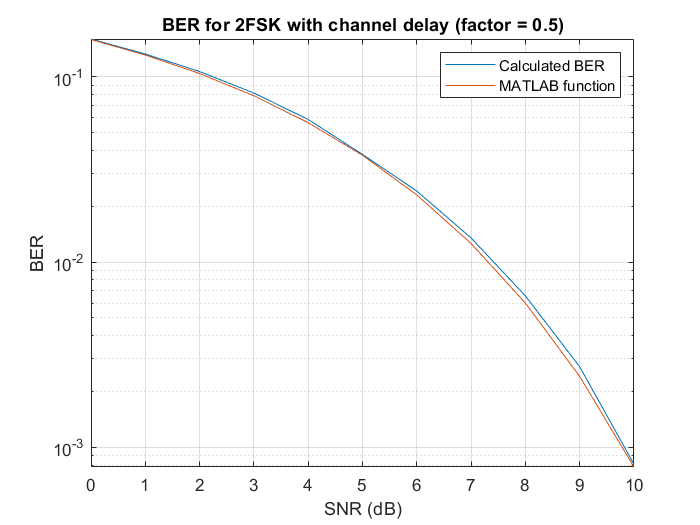

hder_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k);
hder_dec = bi2de(hder_bit, 'left-msb');

b_tx_dec = bi2de(b_tx, 'left-msb');
hder_b_tx_dec = [hder_dec; b_tx_dec];

[tx_smpl] = pulse_modulation(fs, smpl_per_symbl, hder_b_tx_dec, pkt_size, M);
hdr_smpl = tx_smpl(1:length(hder_dec)*smpl_per_symbl);

chnl_delay_in_smpl = fix(0.5*smpl_per_symbl);
tx_sampl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl];
tx_sampl_delayed = tx_sampl_delayed * exp(1j * chnl_phase_offset); %phase offset

Es_avg = sum(abs(cons).^2) / M;
Eb = Es_avg / k;
EbN0 = 0:10;
var_noise = Eb ./ power(10, (EbN0 / 10));

l = length(tx_sampl_delayed);
for c = 1:11
    noise_smpl = (sqrt(var_noise(c)/2) * randn(l, 1) + 1j * sqrt(var_noise(c)/2) * randn(l, 1));
    rx_smpl_noise = noise_smpl + tx_sampl_delayed;

    [corr, lags] = xcorr(rx_smpl_noise, hdr_smpl);
    corr = corr(lags >= 0);
    [corr_out_rx_max, idx] = max(corr);
    ang = angle(corr_out_rx_max);

    rx_smpl = rx_smpl_noise(idx_max + length(hdr_smpl):end, 1) * exp(-1j * ang);
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl);
    det_bit = de2bi(det_sym_idx-1, 'left-msb');
    ber(c) = sum((det_bit ~= b_tx), 'all') / (pkt_size * k);
end

ber_MATLAB = berawgn(EbN0, modulation, M, 'coherent');

figure
semilogy(EbN0, ber)
hold on
semilogy(EbN0, ber_MATLAB)
hold off
legend({'Calculated BER', 'MATLAB function'})
xlabel('SNR (dB)')
ylabel('BER')
title('BER for 2FSK with channel delay (factor = 0.5)')
grid

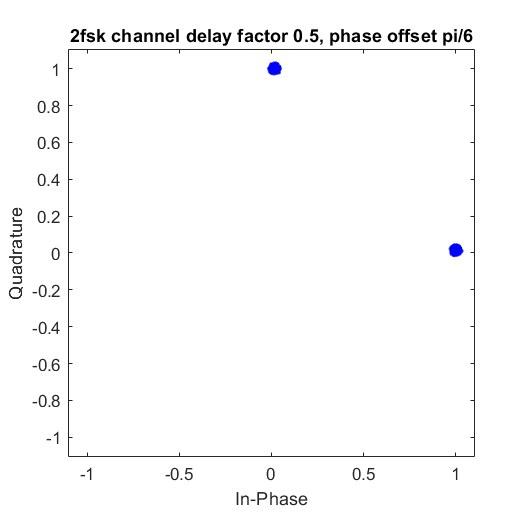



var_noise = Eb / power(10, (40 / 10));

l = length(tx_sampl_delayed);
noise_smpl = (sqrt(var_noise/2) * randn(l, 1) + 1j * sqrt(var_noise/2) * randn(l, 1));
rx_smpl_noise = noise_smpl + tx_sampl_delayed;

[corr, lags] = xcorr(rx_smpl_noise, hdr_smpl);
corr = corr(lags >= 0);
[corr_out_rx_max, idx] = max(corr);
ang = angle(corr_out_rx_max);

rx_smpl = rx_smpl_noise(idx_max + length(hdr_smpl):end, 1) * exp(-1j * ang);
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, 1, 0.5);

title('2fsk channel delay factor 0.5, phase offset pi/6')

By eliminating channel delay and phase offset we can get the same result as part 4.

## Part 5:

### delta f = 1/(2*Ts)

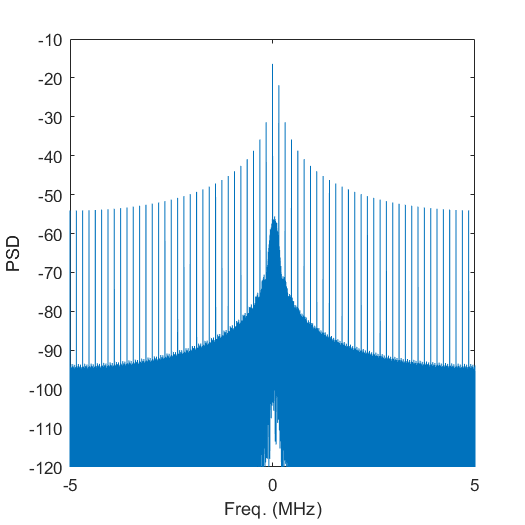

b_tx = bit_gen(pkt_size, k);
b_tx_dec = bi2de(b_tx, 'left-msb');
[tx_smpl] = pulse_modulation(fs, smpl_per_symbl, b_tx_dec, pkt_size, M);

Y = fftshift(fft(tx_smpl));
f = (1:length(Y))/length(Y)*(fs/10^6) - (fs/10^6)/2;
plot(f, 10*log10(abs(Y).^2 / 100) + 30 - 10 * log10(fs^2))
xlabel('Freq. (MHz)')
ylabel('PSD')
ylim([-120 -10])

### delta f = 2 / Ts

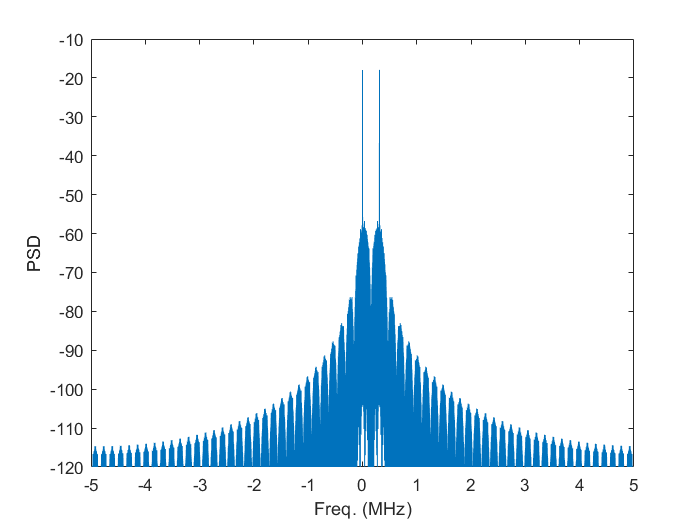

b_tx = bit_gen(pkt_size, k);
b_tx_dec = bi2de(b_tx, 'left-msb');
[tx_smpl] = pulse_modulation(fs, smpl_per_symbl, b_tx_dec, pkt_size, M);

Y = fftshift(fft(tx_smpl));
f = (1:length(Y))/length(Y)*(fs/10^6) - (fs/10^6)/2;
plot(f, 10*log10(abs(Y).^2 / 100) + 30 - 10 * log10(fs^2))
xlabel('Freq. (MHz)')
ylabel('PSD')
ylim([-120 -10])

According to the plots, as delta f increases BW will increase.

## Functions Definition:

### part 1.

#### 1.

function [b] = bit_gen(N, k)
b = int32(randi([0, 1], [N, k]));
end

#### 2.

#### constellation

function [cons] = constellation(M, smpl_per_symbl, fs)
cons = zeros(M * smpl_per_symbl, 1);
t = (0:smpl_per_symbl-1) / fs;
for c = 1:M
    cons((c-1)*smpl_per_symbl + 1:c*smpl_per_symbl) = exp(1j * 2 * pi * double((c-1) * fs / (2 * smpl_per_symbl)) * t) / sqrt(smpl_per_symbl);
end
end

#### 3.

#### pulse shape

function [p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin)
Ts = smpl_per_symbl * fs;
t = (0:smpl_per_symbl-1)/fs;
if strcmp(pulse_name, 'rectangular')
    p = ones(smpl_per_symbl, 1);
elseif strcmp(pulse_name, 'triangular')
    p = (max(Ts/2 - abs(t-Ts/2), 0)).';
elseif strcmp(pulse_name, 'sine')
    p = sin(pi*t.'/Ts);
end
p = p / sqrt(sum(p.^2));
end

#### upsample

function [y] = upsmpl(x, N)
y = zeros(1, (length(x) - 1)*(N - 1) + length(x));
for i = 1:N:(length(x) - 1)*(N - 1) + length(x)
    y(i) = x((i - 1)/N + 1);
end
end

#### pulse modulation

function [tx_smpl] = pulse_modulation(fs, smpl_per_symbl, b_tx_dec, varargin)
pkt_size = length(b_tx_dec);
tx_smpl = zeros(pkt_size * smpl_per_symbl, 1);
t = (0:smpl_per_symbl-1) / fs;
for c = 1:pkt_size
    tx_smpl((c-1)*smpl_per_symbl + 1:c*smpl_per_symbl) = exp(1j * 2 * pi * double(b_tx_dec(c) * fs / (2 * smpl_per_symbl)) * t) / sqrt(smpl_per_symbl);
end
end

### part 2.

#### 1.

function [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, varargin)
flag = 0;
if ~isempty(varargin)
    flag = varargin{1};
end
if mod(length(rx_smpl), smpl_per_symbl) ~= 0
    rx_smpl = [rx_smpl; zeros(smpl_per_symbl - mod(length(rx_smpl), smpl_per_symbl), 1)];
end
row = length(rx_smpl)/smpl_per_symbl; 
rx_sym = zeros(length(rx_smpl), 1);
corr = zeros(row, smpl_per_symbl);
test = zeros(row, M);
cons = constellation(M, smpl_per_symbl, fs);
for c = 1:M
    corr = (cons((c-1)*smpl_per_symbl+1:c*smpl_per_symbl)') .* (reshape(rx_smpl, smpl_per_symbl, row).');
    test(:, c) = sum(corr, 2);
end
[~, det_sym_idx] = max(real(test), [], 2);
for c = 1:row
    idx = det_sym_idx(c) - 1;
    rx_sym((c-1)*smpl_per_symbl+1:c*smpl_per_symbl) = cons(idx*smpl_per_symbl+1:(idx+1)*smpl_per_symbl);
end
if (M == 2 && flag == 1)
    figure
    scatterplot(real(test))
    title(['factor is ', num2str(varargin{2})])
end
end